# **Solving viscoelastic problems with a Laplace transform approach supplanted by ARX models, suggesting a way to upgrade Finite Element or spectral codes**

$\textrm{Stéphane}\;{\textrm{André}}^{1,2}$, $\textrm{Camille}\;{\textrm{Noûs}}^2$

- Université de Lorraine, CNRS, LEMTA, F-54000 Nancy, France

- Cogitamus Laboratory, F-75000, France

**                        ///           This executive and executable paper works on the Matlab R2020b version    ///**

**Abstract:** Finite Element codes used for solving the mechanical equilibrium equations in transient problems associated to (time-dependent) viscoelastic media generally relies on time-discretized versions of the selected constitutive law. Recent concerns about the use of non-integer differential equations to describe viscoelasticity or well-founded ideas based upon the use of a behavior’s law directly derived from Dynamic Mechanical Analysis (DMA) experiments in frequency domain, could make the Laplace domain approach particularly attractive if embedded in a time discretized scheme. Based upon the inversion of Laplace transforms, this paper shows that this aim is not only possible but also gives rise to a simple algorithm having good performances in terms of computation times and precision. Such an approach, which fully relies on the Laplace-defined Behavior or Transfer Function (LBTF) can be promoted if it uses ARX (AutoRegressive with eXogeneous input) parametric models perfectly substitutable to the real LTBF. They avoid the hitherto prohibitive pitfall of having to store all past data in the computer’s memory while maintaining an equal computation precision.

**Keywords:** Laplace transform, ARX models,  Iterative algorithm, Viscoelasticity, Fractional relaxation kernels.

The numbering of the equations follows that given in the original document.

## Viscoelastic constitutive laws

In the following, three constitutive laws will be considered namely the SLS (Standard Linear solid), the DLR (Dynamic or Linear Relaxations) and NIFL (Non-Integer Fractional Law), the first two being defined in the time domain and the third one directly in the Laplace or frequency domain. Because the SLS is a reduction of the DLR approach to a single time of relaxation, with the same mathematical structure, it will be presented as a particular case below. For all constitutive laws, 

- The elastic behavior will be shaped by the instantaneous (Young or glassy) modulus parameter $E^u \;$(*u* upperscript meaning *unrelaxed*).

- The relaxed state will be characterized by the *r*elaxed (or rubber) modulus parameter $E^r$

- The relaxation describing the viscoelastic process from instantaneous to relaxed state will introduce relaxation time(s) denoted by $\tau$

- The DLR approach (Cunat, 2001)

In time domain, this law is formulated through the differential equation: 

$\dot{\sigma}\left(t\right)=\sum_{j=1}^{N}{\dot{\sigma}}_j=\sum_{j=1}^{N}\left(p_j^\ .E^u.\dot{\varepsilon}-\frac{\sigma_j-p_j^\ .\sigma^r}{\tau_j}\right)$  (eq. 6-1)

In Laplace domain, this law leads to the LBTF

 $\bar{H} (p)=\frac{\sigma^‾ \left(p\right)}{\varepsilon^‾ \left(p\right)}=\sum_{j=1}^N p_j^~ \left(\frac{\tau_j E^u p+E^r }{1+\tau_j p}\right)$   (eq. 6-2)

The DLR impulse response in time (inverse Laplace transform of the LBTF) is then $\sigma^{\delta } (t)={\mathcal{L}}^{-1} \bar{H} (p)(t)=\sum_{j=1}^N p_j^~ \ldotp E^u \delta (t)+\sum_{j=1}^N p_j^~ \left(E^r -E^u \right)\frac{e^{-t/\tau_j } }{\tau_j }~$(eq. 6-3)

This law will be referred next as the viscoelastic DLR-behavior

        2. The SLS approach 

It can be considered as a particular case of the DLR approach which includes the SLS approach by considering one single relaxation times. The same mathematical expressions as above are obtained, cancelling the summation term $\sum$.

        3. The Non-Integer or Fractional (NIF-) behavior 

Two of them are considered in the mother paper. One originates from the DLR approach in the asymptotic limit where $N\to \infty$(infinite number of relaxation modes). It has been showed in (Andre et al, 2003) that the associated LBTF is then $\bar{H} \left(p\right)=\frac{\sigma^‾ \left(p\right)}{\varepsilon^‾ \left(p\right)}=E^u +$ $\left(E^r -E^u \right)\frac{{\left(1+\frac{p}{\omega_{\textrm{high}} }\right)}^{n-1} }{{\left(1+\frac{p}{\omega_{\textrm{low}} }\right)}^n }$   (eq. 12) where $\alpha$ is the non-integer parameter and with $\omega_{\textrm{high}} =1/\tau_{\min }$,  $\omega_{\textrm{low}} =1/\tau_{\max }$ defining the bounds of a spectrum of relaxation times covered by the Laplace variable range. 

This transfer function has no  available formal expression in the time-domain.

Because this LBTF appears not so distant from DLR-behavior, a second fractional law with a different mathematical structure has been considered. Its existing time-domain counterpart implies the Mittag-Leffler function. It is based on a relaxation kernel proposed initially by Rabotnov (Sevostianov 2007).

The LBTF is $H\left(p\right)=\frac{\sigma^‾ \left(p\right)}{\varepsilon^‾ \left(p\right)}=E^u +$$\left(E^r -E^u \right)\mathcal{L}\left\lbrack \owns_{\alpha }^{\mathrm{*}} {\left(\beta ,\mathrm{t}\right)}\right\rbrack =E^u +\left(E^r -E^u \right)\frac{1}{p^{1-\alpha } +\beta }$  (eq. 13) where $\alpha$ is the non-integer parameter and

with $\owns_{\alpha }^{\mathrm{*}} {\left(\beta ,\mathrm{t}\right)}=E_{\alpha +1,\alpha +1} \left(\beta t^{\alpha +1} \right)=t^{\alpha } \;\sum_{n=0}^{\infty } \frac{{\left(\beta t^{1+\alpha } \right)}^n }{\Gamma \left\lbrack \left(n+1\right)\left(1+\alpha \right)\right\rbrack }$  (eq. 14)

This fractional kernel describes the delayed component of the full response. Therefore, the impulse response in time (inverse Laplace transform of the LBTF) is then

 $\sigma^{\delta } (t)={\mathcal{L}}^{-1} \bar{H} \left(p\right)(t)=\;E^u \delta (t)+\left(E^r -E^u \right)\owns_{\alpha }^{\mathrm{*}} {\left(\beta ,\mathrm{t}\right)}~$(eq. 15)

## Example of computation: time response to a 3-step ramp

global t dt dtp dexc1 chxExc slop fs ftconv paramexc fsexcit

**Time vectors and excitation parameters**

dt=0.01; 
t = [dt:dt:10];n = length(t); % 1st temporal vector
dtp=1e-4; 
tp = [dtp:dtp:10];np = length(tp); % 2nd temporal vector with smaller time step
ratio=dt/dtp; % useful for plotting facilities 

**3-ramp excitation**

ti1=pi;ti2=pi+3*pi/4;      % Location of singularities for the C0 excitation function
npi1=find(t-ti1>=0, 1 );   % first/second ramp discontinuity index
npi2=find(t-ti2>=0, 1 );   % second/third ramp discontinuity index
a=0.1;b=0.2;c=-0.1;        % Slope increments w.r.t to the previous one 
paramexc=[a b c ti1 ti2];  % a is the slope of Ramp_1, a+b = slope of Ramp_2, a+b+c = slope of ramp_3
% strain excitation made of 3 ramps (time-domain) - see Table 1 original article
chxExc=3;
fexcit=@(t,dblslop) dblslop(1)*t+dblslop(2)*(t-dblslop(4)).*heaviside(t-dblslop(4))...
    + dblslop(3)*(t-dblslop(5)).*heaviside(t-dblslop(5));
exc1=fexcit(t,paramexc);    % compute the 3-ramp strain loading path
exc3ramp=exc1;              % Save this excitation as the 3-ramp one
% strain excitation made of 3 ramps (Laplace domain) - see Table 1 original article
fsexcit=@(s,dblslop) dblslop(1)./s.^2+dblslop(2).*exp(-s*dblslop(4))./s.^2+...
    dblslop(3).*exp(-s*dblslop(5))./s.^2;
% Figure showing the excitation
figexc = figure(10);
axes10 = axes('Parent',figexc,'YTick',[0 0.5 1. 1.5 2.]);
hold(axes10,'on');
plot(t,exc3ramp,'DisplayName','strain path (excitation)',...
    'Parent',axes10,...
    'Marker','none',...
    'LineStyle','-',...
    'Color',[0 0 0]);
title('3-ramp excitation')
xlabel('time (s)');
ylabel('Strain')
grid on
legend10 = legend(axes10,'show');

**Behavior's law parameters (NIF Behavior with Rabotnov model)**

Eu= 1000 ; % instantaneous or unrelaxed modulus (in MPa)
Er= 100 ; % relaxed modulus (in MPa)
tau = 1; % relaxation time (in s): 1/tau will be the Beta parameter of the Rabotnov law
alpha = 0.4; % non-integer parameter of Rabotnov's law
% RESTRICTIONS HERE:
% Computations of arx models available only for alpha values of 0.2, 0.4, 0.6, 0.8
% Computations of the convolution response for small time steps can be made available
% for any alpha value by uncommenting appropriate lines 66-69 (results for alpha value
% of 0.4 already saved in Out1NIFYmlconv_fine_alf04.mat)
beta=[Eu Er tau alpha]; % parameter vector is named beta
% Behavior's law model = Material Transfer Function (Laplace form)
fs='fcnTftMat';  % Rabotnov fractional model
% Behavior's law model = Material Transfer Function (Time dependence)
ftconv='fcnTftMatConv';  % Mittag-Leffler expression for Rabotnov fractional model

**Computation of the response with full-LBTF approach (Laplace Behaviral Transfer Function)**

We use preferentially De Hoog's algorithm to perform numerical Laplace inversion (De Hoog et al., 1982)

u=1;	% Selection variable for Laplace inversion algorithm,  De Hoog's algorithm
yi1=Ilap(t,'fcnhe',u,beta); % (eq. 3.2)
% fcnhe function realizes the product in Laplace domain of LBTF x Excitation
% Create figure
fig1 = figure(1);
axes1 = axes('Parent',fig1,'YTick',[0 200 400 600 800]);
hold(axes1,'on');
X1= t(1:45:end);Y1=yi1(1:45:end);
plot(X1,Y1,'DisplayName','full-LBTF',...
    'Parent',axes1,...
    'Marker','o',...
    'LineStyle','none',...
    'Color',[0 0 0]);
title('Response to a 3-steps ramp: NIF Rabotnov Model')
xlabel('time (s)');
ylabel('Stress response (MPa)')
grid on
legend1 = legend(axes1,'show');

**Computation of the response as a convolution product (directly in time domain)**

In linear viscoelasticity, the knowledge of the impulse response in time allows the computation of the response to any input signal. If this signal is the strain described through a given $\ell$oading *p*ath  $\varepsilon^{\ell p} \left(t\right)$ then the stress response is obtained through $\sigma \left(t\right)={\left(\sigma^{\delta } *\varepsilon^{\mathcal{l}p} \right)}\left(t\right)=\int_0^t \sigma^{\delta } \left(t-\tau \right)\varepsilon^{\mathcal{l}\mathrm{p}} \left(\tau \right)d\tau$    (eq. 5)

with $\sigma^{\delta }$(t) described in the present case with eq. 15.

The following commented code lines can produce the resut. As it takes much longer computation time due to the necessary lowering of the time step when using the buit-in Matlab function, the response has been calculated once and stored in the matlab data file 'ExePaper_ConvData.mat'.

% Ftt2=fcnTftMatConv(tp,beta);% impulse response for a fine discretized time vector (delayed response only)
% exc2=fexcit(tp,paramexc);   % Input-Excitation for same time vector
% y_conv2=conv(Ftt2,exc2)*dtp;% Convolution of both for the delayed component 
% yi1_conv2=beta(1)*exc2+(beta(2)-beta(1))*y_conv2(1:np);   % Full response (eq. 5)
% save ExePaper_ConvData tp yi1_conv2 Ftt2
load('ExePaper_ConvData')  % previous lines already executed
X2=tp(ratio:ratio:end);
Y2=yi1_conv2(ratio:ratio:end);
figure(fig1);
plot(X2,Y2,'DisplayName','Convolution $\sigma^{\delta} \star \epsilon^{  \ell p} - \Delta t/100$',...
    'Parent',axes1,...
    'Marker','none',...
    'LineStyle','--',...
    'LineWidth',2,...
    'Color',[0 0 0]);
set(legend1,'Interpreter','latex')
% Create legend
legend1 = legend(axes1,'show');

## Towards an incremental time-step approach (step-LBTF approach):

Now we turn our attention to the computation of the same viscoelastic response using the LBTF but in an incremental scheme. This means, the time domain being discretized, the computation of the output stress as  $\sigma (t+\Delta t)=\sigma (t)+\Delta \sigma^t$ . This can be readily achieved applying Duhamel's well known theorem (Özisik, 1993).

####             Discretized description of the input: the strain loading path $\varepsilon^{\ell p} (t)$

-      From a given loading path (as is the case here) but also in view of an incremental numerical approach, the input signal is described over time steps $\Delta t=\left\lbrack t_k ;t_{k+1} \right\rbrack$ through slope variations ${\Delta S}_k =S_k ~-~S_{k-1}$ referring to time $t_k$ with $S_k ={\left(\varepsilon^{\mathcal{l}p} {\left(t_{k+1} \right)}-\varepsilon^{\mathcal{l}p} {\left(t_k \right)}\right)}/\Delta t$. The figure below gives the scheme.

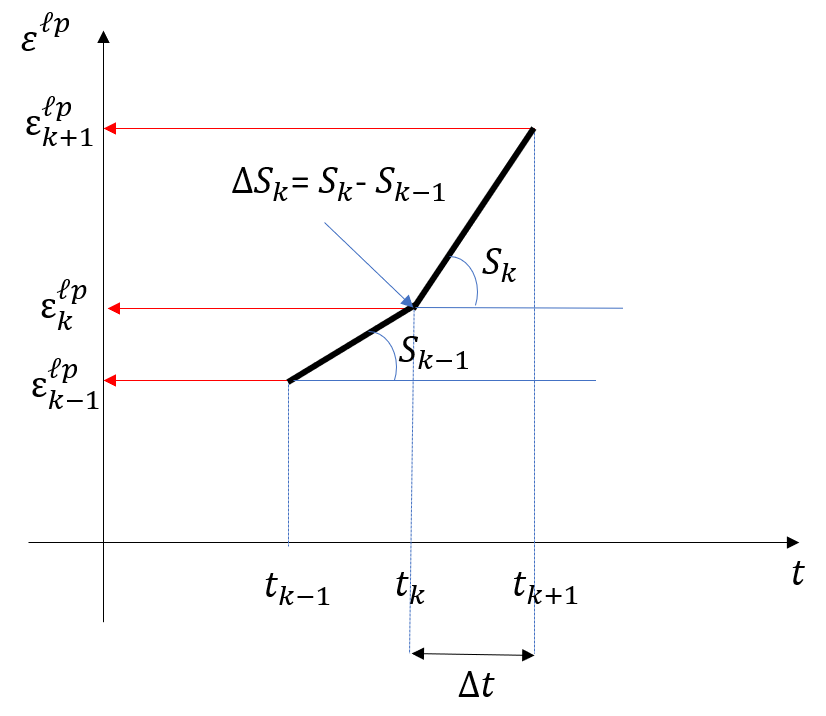

Figure 1 (original paper): Discretization of the input $\varepsilon^{\mathcal{l}p}$ in terms of slope variations.

####             Computation of the URSS-response

-       The time response over a single time step to a **U**nitary **R**amp **S**tucked at a **S**tationnary value (urss) is calculated once for all and stored as a vector. This implies that the time step must remain the same for the numerical application considered in a more general problem, like the mechanical simulation of a composite with viscoelastic constituents. The urss excitation is then described by $\;\varepsilon^{\ell p} \left(t<0\right)=0\;$; $\varepsilon^{\ell p} \left(0<t<\Delta t\right)=t$ ; $\varepsilon^{\ell p} \left(t>\Delta t\right)=\Delta t$.

-       The urss-response is computed for example through DeHoog Laplace inversion (using the LBTF approach) for all time  steps $t_k$.

            $\sigma_0^{{_-\nearrow}^-}(t)=\mathcal{L}^{-1}\left\{\bar{H}(p)\frac{1}{p^2}\left(1-e^{-p\Delta t}\right)\right\}$  (eq. 7)

            Subscript '0' refers to the time origin where this excitation takes place.

####             Incremental approach

-  While the problem can be solved through Laplace inversion as $\sigma (t)={\mathcal{L}}^{-1} \left\lbrace \bar{H} (p)\varepsilon^{\ell p} (p)\right\rbrace$ (eq. 3.2), we look here for an incremental scheme $\sigma (t+\Delta t)=\sigma (t)+\Delta \sigma^t$ where $\Delta \sigma^t$ will be computed solely using the urss-response thanks to Duhamel's theorem application. Indeed, one can consider that $\sigma(t)=\int_{0}^{t}{\sigma^{\delta}(t-\tau)\varepsilon^{\ell p}(\tau)d\tau}=\int_{0}^{t}{\sigma^{h}(t-\tau)\dot{\varepsilon}^{\ell p}(\tau)d\tau}=\int_{0}^{t}{\sigma^{r}(t-\tau)\ddot{\varepsilon}^{\ell p}(\tau)d\tau}$ where $\sigma^{\delta},\sigma^{h},\sigma^{r}$ denote respectively the impulse ($\delta$-dirac), step (**h**eaviside) and **r**amp responses (Transfer function, Relaxance and Ramp respondance in Laplace domain). Using the Stieltjes convolution formulation gives  $\sigma(t)=\sigma^r*\ddot{\varepsilon}(t)=\int_{0}^{t}{\sigma^r(t-\tau)d\dot{\varepsilon}(\tau)}$ (Tschoegl, 1989) which can be discretized between two time-steps.

- The input signal (whatever form) is decribed here with a piecewise continuous sequence of affine functions. That is $\varepsilon(t) = \Delta S_1R(t)+\Delta S_2R(t-\Delta t)+\Delta S_3R(t-2\Delta t)+...$ Jumps in slopes ${\Delta \;S}_k \;$are considered at each time steps $t_k$ (Figure 1) 

- Now we want to introduce the urss-response function $\sigma_0^{{_-\nearrow}^-}(t)$ instead of the pure ramp response $\sigma^r$. This lead to the convolution $\sigma(t_k)=\sigma_0^{{_-\nearrow}^-}* \sum_{i=1}^{n} (\sum_{k=1}^{i}S_k)\delta(t_k-(i-1)\Delta t))(t_k) $  to compute the stress response at time $t_k$. The same applies for time $t_{k+1}$ and one can then compute y difference the expression of the stress increment $\Delta \sigma^t= \Delta S_1 \sigma_0^{{_-\nearrow}^-}(t_{k+1}) + \Delta S_2 \sigma_0^{{_-\nearrow}^-}(t_{k})+\Delta S_3 \sigma_0^{{_-\nearrow}^-}(t_{k-1})+...$        (Eq. 8)

- By the invariant translation property, $\Delta \sigma^t$ appears then to be the “cumulative” dot product of the backward URSS-Response originating recursively from time $t_k$ with the vector of slope increments up to time $t_k$. Calling $r_k$ the coefficients at time $t_k$ of $\sigma_0^{{_-\nearrow}^-}(t_k)$, we then have $\sigma_{k+1}= \sigma_{k}+  \Delta S_{1}r^{k+1}+  \Delta \sigma_{k}$       and     $\Delta \sigma_{k}=   \Delta S_{2}r^{k}+\dots+\Delta S_{k}r^{2}$                                                                                                                              

- In control theory, this constitutes the weighting sequence description (Phan & Longman 1996) linking the input (step strain rates) to the output (stress                 increments).

####     **        Computation of the **incremental time-step approach

This approach is referred to next (and in the original article) as step-LBTF approach to mean that it will proceed according to the basic incremental formula given above, based on the URSS-response (Eq. 7)

% Step 1: Discretized description of the input: the strain loading path
exc1=[0 exc1];
dexc1=diff(exc1);  % for all type of excitation except crenel excitation
slop=dexc1./dt; % Slope sequence
sauts=diff(slop);   % Slope jump sequence
% Step 2: Computation of the URSS-response 'urss'
% fcn_urss function realizes the product in Laplace domain shown in Eq. 7 braces
urss=Ilap(t,'fcn_urss',1,beta);
% for k=1:(length(t))
%     urss(k)=Ilap(t(k),'fcnHtxi',4,[beta 0]); % fcnHtxi equivalent to fcnhe
% end
A1=a*urss; % response to the initial ramp (strain-rate a as initial slope of strain over dt)
yi3(1)=A1(1);
% Step 3: incremental approach
for k=1:(length(t)-1)
    A2 = dot(sauts(1:k),urss(k:-1:1));
    yi3(k+1) = yi3(k) + A1(k+1) + A2; 
end
X3=t;Y3=yi3;
figure(fig1)
plot(axes1,X3,Y3,'DisplayName','step-LBTF',...
    'Parent',axes1,...
    'MarkerSize',5,...
    'LineStyle','--',...
    'LineWidth',2,...
    'Color',[1 0 1]);
% Create legend
legend1 = legend(axes1,'show');

## The step approach achieved with ARX parametric models. 

####             ARX approach a for Linear Time Invariant system

ARX AutoRegressive models with eXogeneous inputs (Ljung, 1998) are parametric models which are shown in this paper to be very suited for being substituted to Laplace transforms and at the same time, providing an incremental approach of time domain computations. When the convolution problem requires the all input history, autoregressive models provide the model output at a given time as a linear combination of the only $\textrm{na}$ previous time steps of the output history and $\textrm{nb}$ time steps of the input history. Retardation or delay can be considered using $\textrm{nk}$ time steps. The structure of the model is given as

$\sigma_{ARX}\left(t\right)=-\sum_{i=1}^{na}{a_i\sigma_{ARX}\left(t-\tau_i\right)}+\sum_{j=1}^{nb}{b_j\varepsilon_{id}\left(t-\tau_{j+nk}\right)}$    (eq.10)

where $\tau_i=i\Delta t$ for $i\geq1$, $\sigma_{ARX}(t)=0$ for $t\le0$ and $\varepsilon_{id}(t)$denotes the ideal (strain) excitation imposed on the (material REV) system.

Coefficients $a_i,b_j$ are the observer Markov parameters. They have to be identified for a selected triplet $\left(na,nb,nk\right)$ – thus the common notation $ARX(na,nb,nk)$ used hereafter - during a so-called *calibration experiment*. 

The *calibration experiment* will be made from a first simulation obtained in a direct way for a given strain excitation, for example the response to a  crenel (see Table 1, original paper) calculated for example with the step-LT approach. The$ARX(na,nb,nk)$ model  will be identified then using the functions available in the System Identification Toolbox of Matlab. Practically we will not use (eq. 5-6) butt rather a state-space representation, classical in control theory. This representation corresponds to

${x\left(k+1\right)=Ax\left(k\right)+B\varepsilon\left(k\right)\\\sigma\left(k\right)=Cx\left(k\right)+D\varepsilon\left(k\right)}$              (eq. 11)

where $x\left(k\right)$ is the state variable having no physical meaning here, $\sigma \left(k\right)$ the output (stress) observable, $\varepsilon \left(k\right)$ the input (strain) signal. Matrix $A$ is $n\times n$, $B$ is $n\times 1$, $C$is $1\times n$ and $D$ is $1\times 1$. Number $1$ simply results from a case with  'single input-single output' signals (SISO model). These matrices are also given as direct outputs from the System Identification Tbox Matlab. Note that in a FEM of spectral solver code, the state vector $x$ $\left(n\times 1\right)$ would have to be saved for each integration points or voxel from current to next time-step. Additionnaly, in the state-space representation  of Eq. 10, the stress output is computed from the current strain value instead from a few past input-output set of values as in the pure ARX approach of Eq. 11.

####             **Computation of the **incremental ARX approach

Identification was performed separately in this case of the NIF Rabotnov model from the crenel excitation as calibration experiment (see original paper). The matlab OutYML_ARX_IdModels_alfa.mat file contains the results of the identification ('structure' variables of *idpoly* type) performed for the four $\alpha$ (alfa) values considered in the article for the Mittag-Leffler function. An $ARX(1,3,0)$ model was found sufficient to produce excellent fitting errors on the validation experiment (the 3-ramp excitation here).

% Loading the ARX(1,3,0) models identified for case4 (3-ramps + relaxation)
load('OutYML_ARX_IdModels_alfa.mat')
% Extract matrices A,B,C,D from the idpoly structure for alfa=0.4
[A, B, C, D] = ssdata(arx130Id4alf02);
% Compute the output using a function for eq.5-7
[nS,ny] = size(A);              %number of states nS (= ny)
[mx,~] = size(B);                   %number of inputs m=1
[p,py] = size(C);                       %number of outputs p=1
yi4_130 = zeros(length(t), 1);
%yi4_130(1,1) = Ilap(t(1),'fcnhe',4,beta);
x0 = zeros(nS, 1);   % initialisation of state vector
x = reshape(x0, [], 1);
for k = 0:n-1   % simple loop over time steps
    yi4_130(k+1, :) = C * x  +  D * exc1(k+1);
    x = A * x  +  B * exc1(k+1);      % updating the state vector
end
X4=t;Y4=yi4_130;
figure(fig1);
plot(axes1,X4,Y4,'DisplayName','ARX(1,3,0) Identified on 3 ramps+dwell',...
    'Parent',axes1,...
    'MarkerSize',5,...
    'LineStyle','--',...
    'LineWidth',2,...
    'Color',[0.078 0.168 0.549]);
% Create legend
legend1 = legend(axes1,'show');
% set(legend1,...
%     'Position',[0.6 0.14 0.26 0.24],...
%     'Interpreter','latex',...
%     'FontSize',12,...
%     'AutoUpdate','off');

## References

André, S., Meshaka, Y., & Cunat, C. (2003). Rheological constitutive equation of solids : A link between models based on irreversible thermodynamics and on fractional order derivative equations. *Rheologica Acta*, *42*(6), 500‑515. [https://doi.org/10.1007/s00397-003-0305-z](https://doi.org/10.1007/s00397-003-0305-z)

Cunat, C. (2001). The DNLR Approach and Relaxation Phenomena. Part I – Historical Account and DNLR Formalism. *Mechanics of Time-Dependent Materials*, *5*(1), 39‑65. [https://doi.org/10.1023/A:1009899519935](https://doi.org/10.1023/A:1009899519935)

de Hoog, F. R., Knight, J. H., & Stokes, A. N. (1982). An Improved Method for Numerical Inversion of Laplace Transforms. *SIAM Journal on Scientific and Statistical Computing*, *3*(3), 357‑366. https://doi.org/10.1137/0903022

Ljung, L. (1998). System Identification. In A. Procházka, J. Uhlíř, P. W. J. Rayner, & N. G. Kingsbury (Éds.), *Signal Analysis and Prediction* (p. 163‑173). Birkhäuser. [https://doi.org/10.1007/978-1-4612-1768-8_11](https://doi.org/10.1007/978-1-4612-1768-8_11)

Özisik, N. (1993). The Use of Duhamel’s Theorem. In *Heat Conduction* (2nd éd., p. 195‑213). John Wiley & Sons.

Sevostianov, I., Levin, V., & Radi, E. (2015). Effective properties of linear viscoelastic microcracked materials : Application of Maxwell homogenization scheme. *Mechanics of Materials*, *84*, 28‑43. [https://doi.org/10.1016/j.mechmat.2015.01.004](https://doi.org/10.1016/j.mechmat.2015.01.004)

Tschoegl, N. W. (1989). *The Phenomenological Theory of Linear Viscoelastic Behavior*. Springer. https://doi.org/10.1007/978-3-642-73602-5

## ADDENDUM_1-

### Mittag-Leffler function and Rabotnov relaxation kernel (figure 8 of original paper)

The Mittag-Leffler function and its Laplace transfor are recalled below


$$\ni_\alpha^\ast(\beta,t)=E_{\alpha+1,\alpha+1}(\beta t^{\alpha+1})=t^\alpha\sum_{n=0}^{\infty}\frac{\left(\beta t^{1+\alpha}\right)^n}{\Gamma\left[\left(n+1\right)\left(1+\alpha\right)\right]}$$
     
$$\to^{\textrm{Laplace}\;\textrm{Transform}}$$
  
$$\frac{1}{p^{1-\alpha}+\beta}$$


The figure shows the influence of the non integer $\alpha$ value, $\beta$ being the second physical parameter of this law ans set to 1 here.

dt1=0.01; % time-step
t1 = logspace(-3,1)';
n1=length(t1); % nbr times
nstep=n1-1;   % Nbr of time intervals
step=4;  % Nbr of intervals for linear piecewise ramps:  integer, multiple of nstep
I=[1:step:n1]; % indices of discretization (one jump every step points)
np1=length(I);  
% ##########################
% Physical model parameters are alfa and beta (characteristic frequency)
mu=2;beta=1;gam=50; 
alfa=[0.2 0.4 0.6 0.8]';
pvec1 = [mu*ones(size(alfa)) -alfa -beta*ones(size(alfa)) gam*ones(size(alfa))];
% Rabotnov kernel in time domain for each alfa value (Mittag Leffler functions)
for i=1:4
    yk_t(:,i)=t1.^pvec1(i,2).*(mlf(pvec1(i,2)+1,pvec1(i,2)+1,pvec1(i,3)*t1.^(1+pvec1(i,2)),9));
end
% Rabotnov kernel in time domain for each alfa value using Laplace inverse
pvec = [mu*ones(size(alfa)) alfa beta*ones(size(alfa)) gam*ones(size(alfa))];
for i= 1:4
    yk_ilap(:,i)=invlap('Rabotnov',t1,0,1e-9,pvec(i,:));
end
% #########################
% Plot of Kernel Rabotnov in time (ML), compared to Laplace inverse of 1/(p^1-alfa + beta)
YMatrix1=[yk_t(:,1),yk_ilap(:,1)];
YMatrix2=[yk_t(:,2:4),yk_ilap(:,2:4)];
fig2 = figure(2);
figure(fig2)
axes2 = axes('Parent',fig2,'XLim',[0 2.5],'YLim',[0 2.],'XTick',[0 0.5 1.0 1.5 2.0 2.5],...
   'YTick',[0 0.2 0.4 0.6 0.8 1 1.2 1.4 1.6 1.8 2.]);
axes3 = axes2;
hold(axes2,'on');
cfig_kernel(t1(1:end-7),YMatrix1(1:end-7,:),YMatrix2(1:end-7,:),fig2,axes2,axes3)
title('NIF Rabotnov Model')
xlabel('time (s)');
ylabel('Mittag-Leffler function')
hold off

## ADDENDUM_2-

### ARX model identification

Recourse is made to Matlab System Identification App. Here we identify the ARX model on the behavior's response to a crenel excitation. The response is based on the step-LBTF algorithm which is more precise.The same code is used as in section "step_LBTF Approach" but with an excitation in form of a crenel. The input (strain path) and output (stress response) are converted to the Matlab iddata format through the command

>> calib1YML04=iddata(yi3',exc1',dt);

This was done elsewhere and the calib1YML04 object made available within the present package. The following code allows first obtaining the ARX(na,nb,nc) identification and secondly to compute the ARX response to a different excitation (the 3-steps ramp used as a guideline in this executable paper). Because the crenel excitation makes it more difficult to adjust an ARX model, an ARX(4,6,0) was required. Figure 1 shows how this ARX460 model simulates the reponse to the 3-ramp case. 

% Identification of an ARX model
% dataset for calibration : the output from step-LBTF algorithm
% is used for previously simulated response of the behavor's law to a
% crenel excitation
load('Out1NIFYmlconv_fine_alf04.mat') % Data set obtained for a crenel excitation
% Parameters of the ARX model
na = 4;
nb = 6;
nk = 0;
Opt = arxOptions;                                    
Opt.Focus = 'simulation';                            
Opt.InitialCondition = 'zero';
[sys,ic] = arx(calib1NIFYmlalf04,[4 6 0], Opt);
% compute now the ARX response to excitation exc1 (3-ramp) with the state-space
% matrix form
[A, B, C, D] = ssdata(sys); % extract matrix A,B,C,D from identified ARX in sys
% load('Out1YML04_arxId.mat')
% [A, B, C, D] = ssdata(arx460_NIFYml04_Id1) % extract matrix A,B,C,D from identified ARX in sys
Y5=fcnARXSS(A,B,C,D,exc3ramp,beta); % Compute the response to 3ramp excitation
% plotting the result
figure(fig1)
plot(axes1,X4(1:20:end),Y5(1:20:end),'DisplayName','ARX(4,6,0) Identified on crenel',...
    'Parent',axes1,...
    'Marker',"pentagram",...
    'MarkerSize',3,...
    'MarkerEdgeColor',[0.0 0.45 0.74],...
    'MarkerFaceColor',[0.0 0.5 0.0],...
    'LineStyle','--',...
    'LineWidth',2,...
    'Color',[0.74 0.37 0.74]);
% Create legend
set(legend1,...
    'Position',[0.6 0.14 0.26 0.24],...
    'AutoUpdate','on');
legend1 = legend(axes1,'show');
%close(fig1)

### Comments on the Figure

In this figure, the three different approaches used for the computation of the stress response to a 3-ramps strain excitation function are compared when this response is base on the viscoelastic physical model. The full-LBTF and step-LBTF approaches produce the same response for the same time increment of $\Delta \;t=0\ldotp 01s$. So it is when proceeding to a computation of the convolution product in time but then, a time increment $100$ times smaller is required to obtain the same precision. ARX models are then compared to these "true" responses. An ARX(1,3,0) can produce the perfect behavior but only if identified on the same type of calibration experiment, which is not very useful in practice as it may be defective in different conditions. An ARX model identified on a  calibration experiment obtained for the crenel excitation requires more terms. Here, ARX(4,6,0) gives a fitting error of 99% for the crenel excitation and is shown to produce an equally performant computation for the three-ramp excitation. Of course the counterpart is to increase data storage of previous outputs and inputs for any node or voxel of a discretized structure. 

## 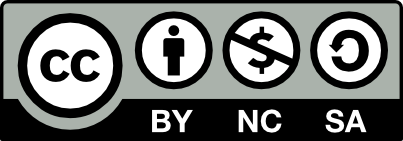

*Copyright 2022 LEMTA Research Laboratory, C.Noûs, S.André*